A system is narrowband if the inverse of the system bandwidth 1/W is much larger than the maximum excess delay 𝜏_max.

Two impulse signals with amplitude a_0 of delay 0 and delay 5μs.

h(𝜏) = a₀*𝛿(𝜏-5μ) + a₀*𝛿(𝜏)

By Fourier transform, we get

H(f) = a₀*[ exp(-j2πf*5μ) + 1]

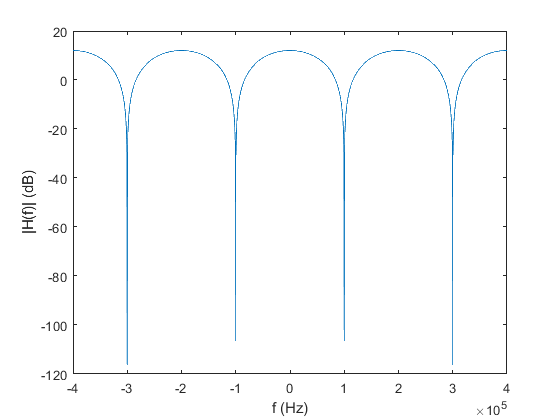

wide_Fs = 8e5;
dt = 1/wide_Fs;
start_time = 0;
stop_time = 5;
t = start_time:dt:stop_time;


a_0 = 2;
n = length(t);
f_range = (-n/2:n/2-1)*((1/dt)/n); 
H = a_0*(exp(-1j*2*pi.*f_range*5e-6)+1);
H_magnitude = sqrt(a_0^2 + a_0^2 + 2*a_0*a_0*cos(2*pi.*f_range*5e-6));


figure;
plot(f_range, 20*log10(H_magnitude))
xlabel("f (Hz)")
ylabel("|H(f)| (dB)")

From the channel response, we can observe the fading dips. This is because there are certain frequencies where the two signals are of opposite phase, and they cancel each other out. (Frequency selective fading) 

If we choose a smaller frequency band (narrow band) in the channel, e.g. 2000 Hz, we can observe flat fading.